# Tweet Sentiment Database

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/tweet_sentiment_extraction/tweet_sentiment_extraction_all-mpnet-base-v2.parquet", "SelectedVariableNames", ["text", "label_text", "embedding"]);

rawData.label_text = categorical(rawData.label_text);

rawData(1:8, :)

ans = 8×3 table
                                                 text                                                 label_text      embedding   
    ______________________________________________________________________________________________    __________    ______________

    " I`d have responded, if I were going"                                                             neutral      {768×1 single}
    " Sooo SAD I will miss you here in San Diego!!!"                                                   negative     {768×1 single}
    "my boss is bullying me..."                                                                        negative     {768×1 single}
    " what interview! leave me alone"                                                                  negative     {768×1 single}
    " Sons of ****, why couldn`t they put them on the releases we already bought"              

groupcounts(rawData, "label_text")

ans = 3×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative        7781       28.314 
     neutral        11118       40.457 
     positive        8582       31.229 


## Preperation

sampleSize = 1000;
contamination =0.2;

positiveIndices = find(rawData.label_text == "positive");
negativeIndices = find(rawData.label_text == "negative");

numNegativeSamples = round(contamination * sampleSize);
numPositiveSamples = sampleSize - numNegativeSamples;

negativeSampleIndices = datasample(negativeIndices, numNegativeSamples, "Replace", false);
positiveSampleIndices = datasample(positiveIndices, numPositiveSamples, "Replace", false);
data = rawData(sort(cat(1, positiveSampleIndices, negativeSampleIndices)),:);

clear positiveIndices;
clear negativeIndices;
clear numNegativeSamples;
clear numPositiveSamples;
clear negativeSampleIndices;
clear positiveSampleIndices;
clear rawData;

data.label_text = removecats(data.label_text);
groupcounts(data, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative        200          20   
     positive        800          80   


unlabeledData = cell2mat(cellfun(@transpose,data.embedding,'UniformOutput',false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.label_text, {'positive' 'negative'}, {'inlier' 'outlier'});

## Separability

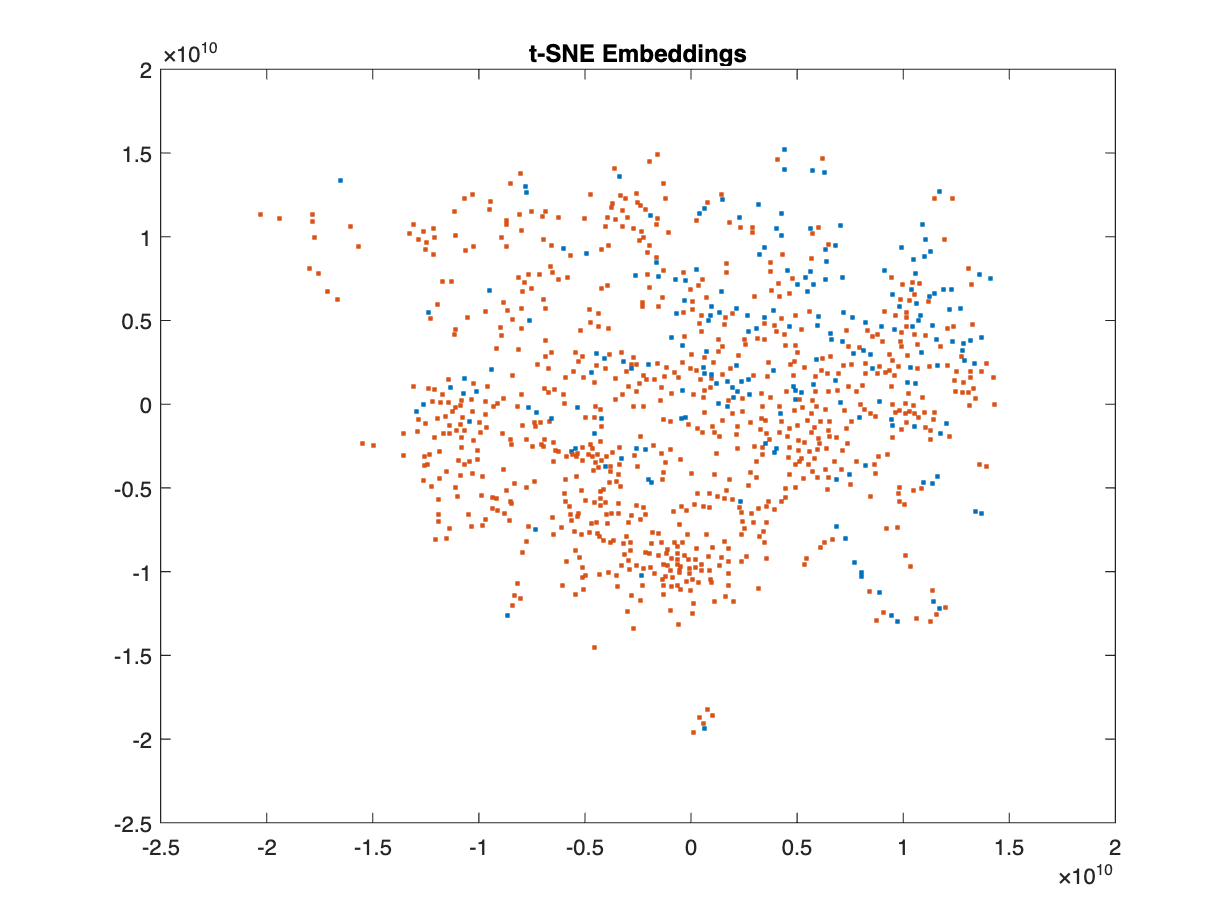

Y = tsne(unlabeledData, Distance="cosine");

figure;
textscatter(Y,data.text,ColorData=labels,TextDensityPercentage=0);
title("t-SNE Embeddings");

clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

ans = 0.8050

## Computation

alpha = 0.7;
% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);

AutoSphereRbfKernel: Sigma = 1.32021208113055


poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SpatialRank


## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative        140          20   
     positive        560          80   


outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

     negative         60        19.802 
     positive        243        80.198 


### Confusion Matrix

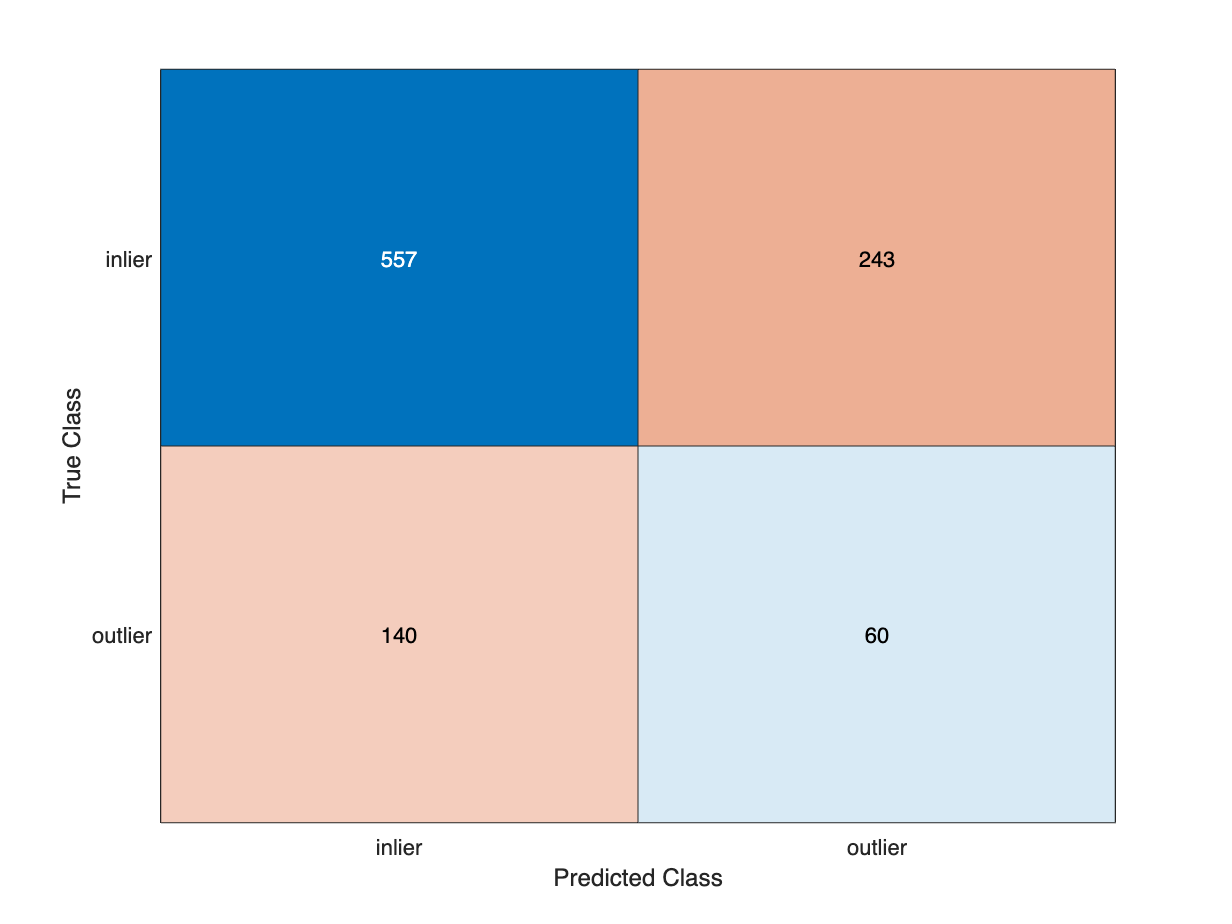

grouphat = categorical(repmat("inlier", size(labels)), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat);
figure;
confusionchart(cm, categories(labels));

struct2table(confusionstats(cm))

ans = 1×5 table
    accuracy    precision    sensitivity    specificity    f1Score
    ________    _________    ___________    ___________    _______

     0.617       0.79914       0.69625          0.3        0.74415


### Mahalanobis Distances

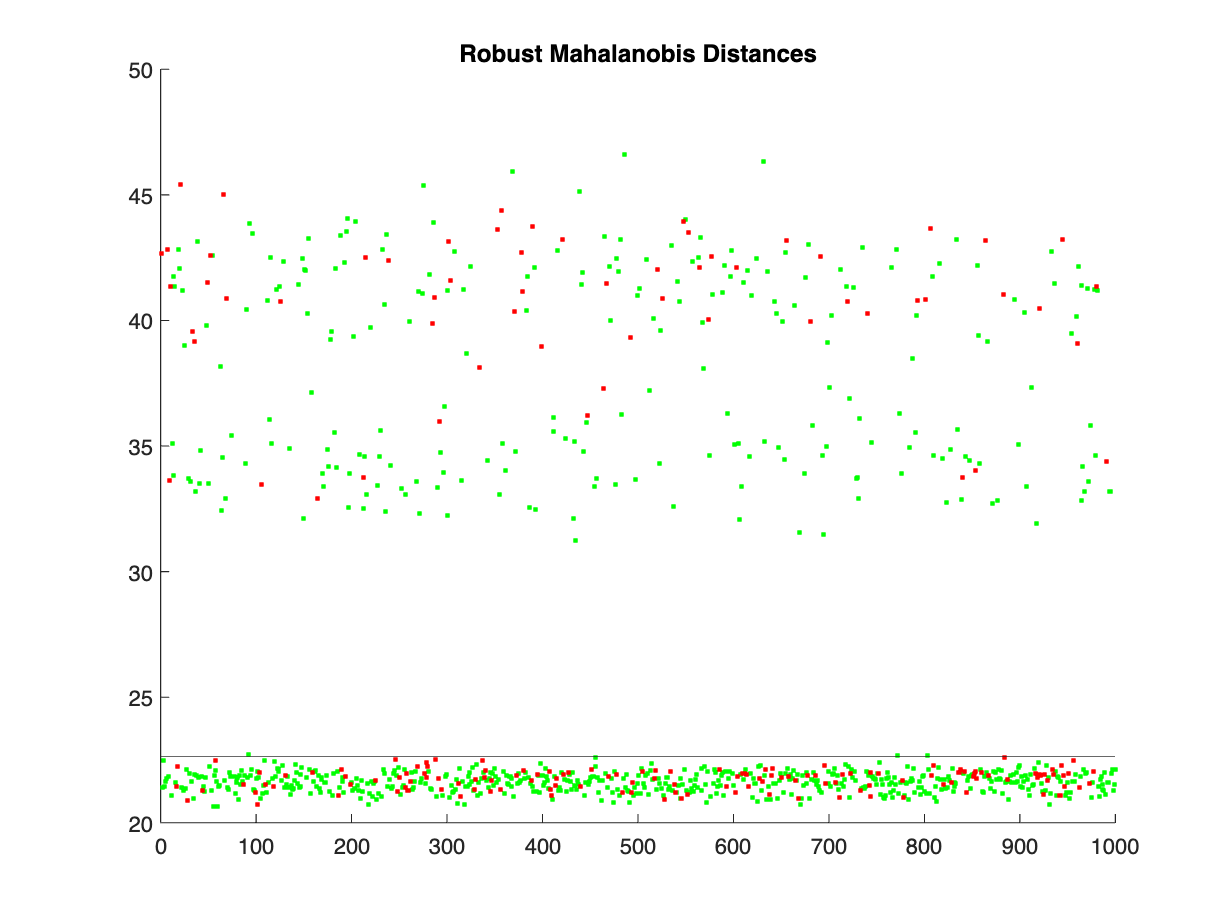

figure;
mahalchart(labels, solution.rd, solution.cutoff);

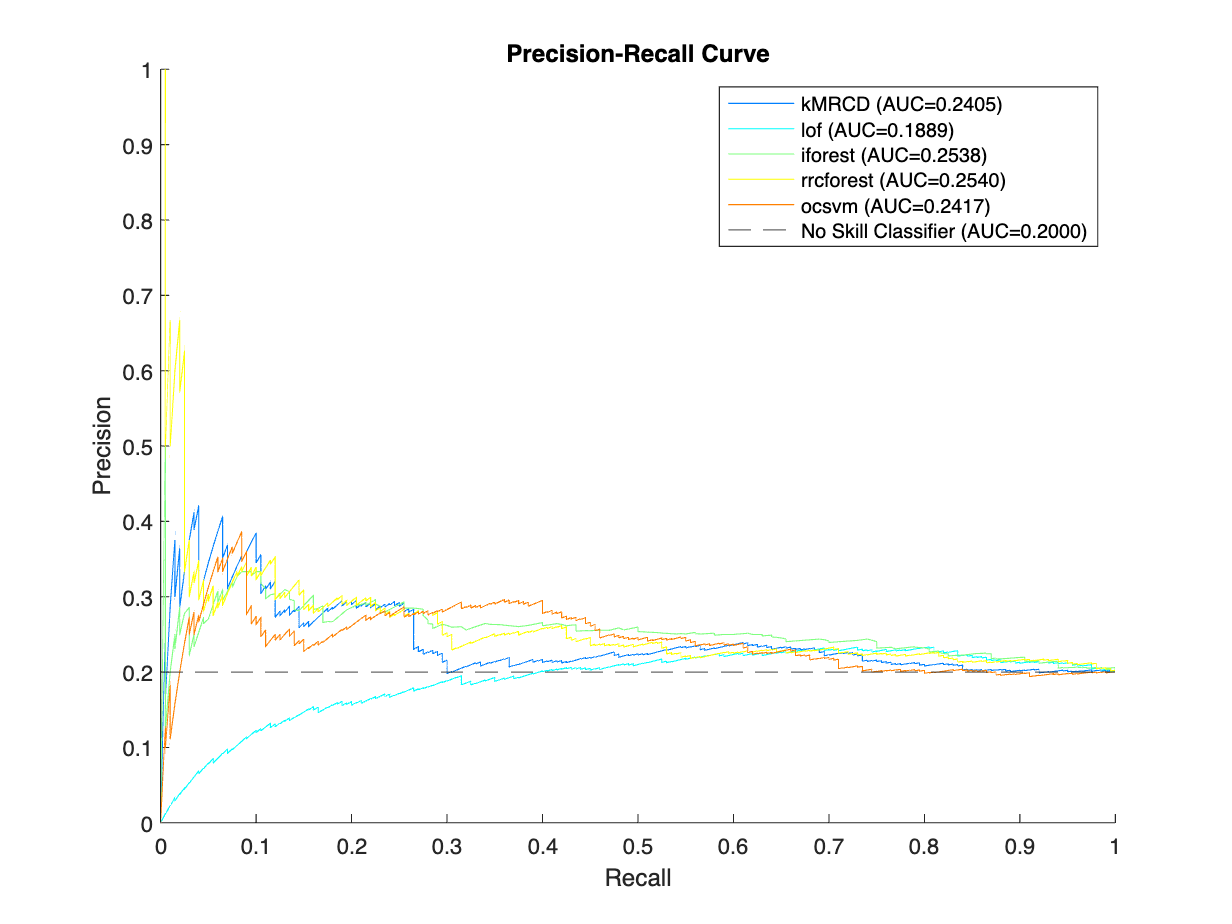

ans = 5×6 table
                 accuracy    precision    sensitivity    specificity    f1Score     aucpr 
                 ________    _________    ___________    ___________    _______    _______

    kMRCD         0.617       0.79914       0.69625           0.3       0.74415    0.24047
    lof           0.606          0.79       0.69125         0.265       0.73733    0.18893
    iforest        0.66       0.82578       0.72875         0.385       0.77424    0.25385
    rrcforest      0.65       0.82143       0.71875         0.375       0.76667    0.25397
    ocsvm         0.668       0.83429          0.73          0.42       0.77867    0.24165


evaluation(unlabeledData, labels, alpha, solution)

% objectiveplot(poc, centredData);
% objectiveplot(poc, unlabeledData);